# Opgave 1: Gram-Schmidt

% Oefening 3
m = 200;
n = 100;

B = randn(m,n);
[Q,~] = qr(B) 

Q =   -0.104719051396005   0.000279491511662  -0.032711705684952   0.014022712979525   0.020990928937504   0.087555345107069  -0.087834310335240  -0.057533502319617   0.059339596422516  -0.055316285101101   0.027125837452493  -0.054501568492522   0.000069297033088  -0.061951633153998   0.100250303209399   0.021241292924204  -0.132162161202512  -0.089205568513765  -0.032369167231077   0.122803555277591   0.018225457844206  -0.050697288525280  -0.040331974260513   0.003707621808644   0.024103136734414   0.057459420061259   0.130732051179892   0.004324550572768  -0.056850881489585   0.001951824515582   0.038491409244185   0.163119000628508   0.043530308837458   0.092632761091985  -0.077777661835260  -0.025735081789490  -0.018492631718070  -0.004984424140296  -0.031410317449801  -0.018222850673670  -0.000932952839394   0.114530877862640   0.068997713865903   0.101895553740251  -0.052775296242713   0.107610290518744   0.042218143150161  -0.031604359837988  -0.000919927627769   0.01168039411


D = eye(m,m);
for i = 1:m
    D(:,i) = D(:,i) * 2^(1-i);
end
display(D)

D =    1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                


V = eye(m,m);
V(1,:) = 1;
display(V)

V =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0   


A = Q*D*V

A =   -0.104719051396005  -0.104579305640174  -0.112896977817243  -0.102966212273564  -0.103407118337411  -0.101982946861409  -0.106091462494993  -0.105168531882877  -0.104487256097479  -0.104827091015343  -0.104692561320368  -0.104745663489995  -0.104719034477784  -0.104726613851224  -0.104712932603084  -0.104718403163189  -0.104721068030545  -0.104719731980481  -0.104719174874579  -0.104718817166812  -0.104719034014854  -0.104719075570356  -0.104719061011897  -0.104719050954022  -0.104719049959346  -0.104719049683581  -0.104719049447945  -0.104719051363784  -0.104719051607791  -0.104719051392369  -0.104719051360157  -0.104719051320047  -0.104719051385870  -0.104719051385221  -0.104719051400532  -0.104719051396754  -0.104719051396274  -0.104719051396041  -0.104719051396119  -0.104719051396038  -0.104719051396006  -0.104719051395953  -0.104719051395989  -0.104719051395993  -0.104719051396008  -0.104719051396002  -0.104719051396004  -0.104719051396005  -0.104719051396005  -0.10471905139


% Oefening 4
e1 = zeros(j)

e1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

e2 = zeros(j)

e2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  


[Q1,~] = klGS(A)

Q1 =   -0.104719051396005   0.000279491511662  -0.032711705684952   0.014022712979525   0.020990928937504   0.087555345107070  -0.087834310335236  -0.057533502319604   0.059339596422221  -0.055316285100414   0.027125837454105  -0.054501568479822   0.000069297055298  -0.061951633109240   0.100250303230141   0.021241292939207  -0.132162153917375  -0.089205753153687  -0.032369515364235   0.122802115921701   0.018233774438203  -0.050673890808286  -0.040358195365927   0.003656635313039   0.024078668905382   0.057479571771143   0.130459721308167   0.110160445779069   0.113548693647741   0.118533269640761   0.119055155276611   0.119508880657528   0.118917857500664   0.118922971413271   0.118823115538547   0.118844780601190   0.118847236408060   0.118848311653630   0.118847982321870   0.118848297764033   0.118848414230415   0.118848591551649   0.118848477332490   0.118848465308635   0.118848424777515   0.118848440643186   0.118848434513989   0.118848432606190   0.118848433116327   0.1188484331

[Q2,~] = modGS(A)

Q2 =   -0.104719051396005   0.000279491511662  -0.032711705684952   0.014022712979525   0.020990928937504   0.087555345107069  -0.087834310335239  -0.057533502319615   0.059339596422518  -0.055316285101092   0.027125837452502  -0.054501568492497   0.000069297033124  -0.061951633154083   0.100250303209582   0.021241292924528  -0.132162161201459  -0.089205568512574  -0.032369167227364   0.122803555284488   0.018225457840953  -0.050697288503685  -0.040331974277912   0.003707621960491   0.024103136965710   0.057459420081099   0.130732052103307   0.004324552091066  -0.056850877274158   0.001951821325345   0.038491426453110   0.163118991185467   0.043530291334365   0.092632883253726  -0.077777414263050  -0.025734416784774  -0.018493559269491  -0.004982230666464  -0.031407121686392  -0.018232732774194  -0.000914696605815   0.114562263002652   0.069028236509413   0.102042832352145  -0.052750706972512   0.107941943591529   0.041036999170719  -0.031639487739392  -0.000082288343158   0.0164111008

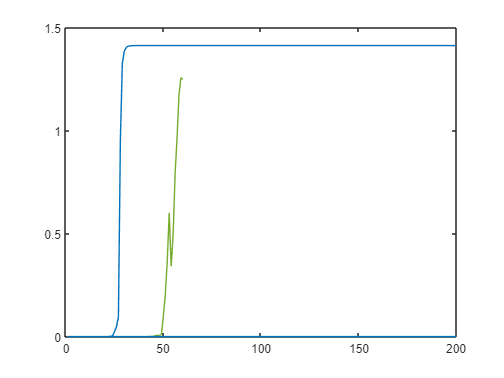


for j = 1:m
    e1(j) = norm(Q1(:,j)-Q(:,j));
    e2(j) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2)
hold off